# 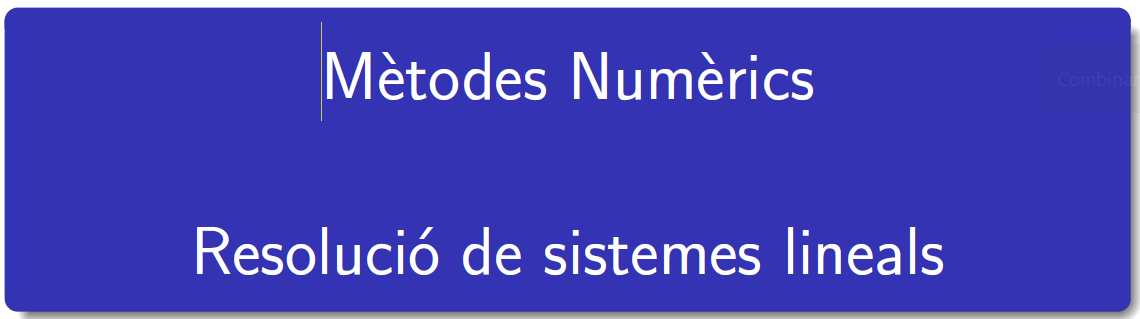

=====================================================================================

# TEMA 2 Àlgebra lineal numèrica

## EXERCICIS - Resolució de sistemas d'equacions lineals

### 1.- Nombre de condició d'una matriu 

Càlcul del nombre de condició d'una matriu en Matlab®: consulteu [condition number of matrix](https://es.mathworks.com/help/symbolic/cond.html).

**Estudieu com varia la solució del sistema lineal quan modifiquem la matriu del sistema **$(A+\Delta)(x+\delta x) = b$ 

`EXERCICI: 1) Consulteu la documentació de l'assignatura i feu una predicció de com petits canvis en A afecten a la solució x del sistema d’equacions Ax = b. ` 

Doncs bé, com és sabut, la solució d'un sistema d'equacions lineals no homogèni pot contenir errors que provinguin de diverses fonts. En un sistema d'equacions lineals, petits canvis en els coeficients(de la matriu A, del vector de termes independents o ambdós) poden provocar grans canvis en la solució, fent-la inestable. En el nostre cas, doncs, el problema raurà en el fet de tenir una matriu de coeficients mal condicionada. Per tant, el nostre sistema d'equacions lineals, construit amb la matriu A, haurà de ser definit com a sistema sensible, o bé també mal condicionat. És per això doncs, que podem predir que la nostra matriu A, tindrà un nombre de condició K(A) >= 1, ja que aquest és una mesura de l'estabilitat o condició de la matriu.

`EXERCICI: 2) Poseu a prova la vostra predicció pel vector b i les matrius A següents:`


$$\left (A|b\right ) = \left (
		\begin{array}{cc|c}
		1 & 1 & 100\\
		1 & 0 & 1\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		1 \\
		99 \\
		\end{array}
		\right)$$
    
$$\left (A|b\right ) = \left (
		\begin{array}{cc|c}
		1 & 1 & 100\\
		1 & 0.01 & 1\\
		\end{array}
		\right ) \stackrel{sol. exacte}{\longrightarrow}
		\left(
		\begin{array}{c}
		? \\
		? \\
		\end{array}
		\right)$$


% Càlculs per fer: resoldre els dos sistemes i comparar les dues solucions obtingudes
A = [1 1; 1 0];
b = [100; 1];
sol = linsolve(A,b); %també sol=A\b
As = [1 1;1 0.01];
solExacteP =linsolve(As,b);

% En efecte, si comprobem amb Matlab el valor del nombre de condició de la matriu A, aquest és major a 1,
% és més major que 1, provocant que el nostre sistema sigui definit com a sensible, tot 
% i només havent variat un 0.01 el valor del coeficient (a22) de la matriu
% A. Cal notar també que en aquest cas, no hem perturbat cap valor del
% vector del terme independent.
cond(A); %K(A) > 1
%També podem calcular-ho fent:
res = norm(A)*norm(inv(A));

%Notem, els paràmetres de condicionament
k = cond(A,1);
rk = rcond(A); %en norma-1
table(k, rk, 'VariableNames',{'Nombre de condició','Nombre de condició recíproc'})

ans = 1×2 table
    Nombre de condició    Nombre de condició recíproc
    __________________    ___________________________

            4                         0.3            



%Com a criteri de comparació entre la solució exacta x i la solució
%calculada x* = x + dx, del sistema lineal Ax=b, definirem el vector r(x*)
%per: r(x*)= Adx = Ax - Ax* = b - Ax*
rx = b - A*solExacteP; %vector residu ens mostra un mal condicionament del sistema
table(sol, solExacteP, 'VariableNames',{'Solució Exacte','Solució Matriu Pertorbada'})

ans = 2×2 table
    Solució Exacte    Solució Matriu Pertorbada
    ______________    _________________________

           1                       0           
          99                     100           


### 2.- Mètode dels mínims quadrats

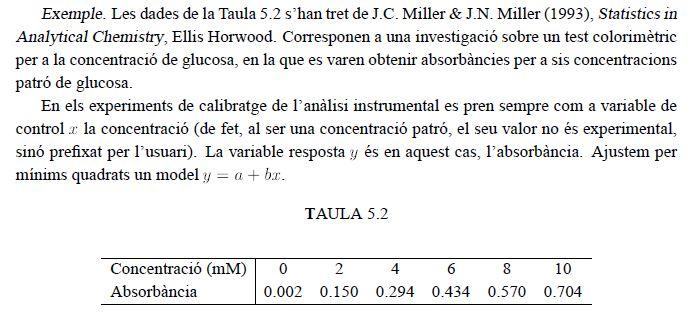

- Gràfica de les dades, correctament retolada

clearvars
x = [0:2:10]';    % Concentració(mM)
y = [0.002; 0.150; 0.294; 0.434; 0.570; 0.704]; % Absorbència

- Recta. La representació gràfica de les dades suggereix que la dependència de l’absorbància respecte a la concentració és lineal. Així, doncs, volem ajustar les dades a una recta y = a + bx. 

`EXERCICI: 1) obteniu els coeficients a i b de la recta.`

p = polyfit(x,y,1);

%Els coeficients de la recta són:
a = p(1);
b = p(2);

table(a, b, 'VariableNames',{'Coeficient a','Coeficient b'})

ans = 1×2 table
    Coeficient a    Coeficient b
    ____________    ____________

      0.070143       0.0082857  


`EXERCICI: 2) representeu les dades i la recta en un mateix gràfic. La gràfica ha d'estar perfectament retolada. `

% Càlculs per fer
plot(x, b + a*x, 'DisplayName',sprintf('lineal'))
grid on
xlabel("Concentració en (mM)")
ylabel("Absorbància")
title("Test colorimètric per a la concentració de glucosa")
legend('show')

xlim([0.0 10.0])
ylim([0.00 0.80])

- Paràbola. Volem obtenir un model millor per mesurar l’absorbància en funció de la concentració de glucosa. Per exemple, proposem un model parabòlic y = a + bx + cx^2

`EXERCICI: 3) obteniu els coeficients a, b i c de la paràbola.`

%Obtenim els coeficients de la paràbola
p1 = polyfit(x,y,2);

a = p1(1);
b = p1(2);
c = p1(3);
table(a, b, c, 'VariableNames',{'Coeficient a','Coeficient b','Coeficient c'})

ans = 1×3 table
    Coeficient a    Coeficient b    Coeficient c
    ____________    ____________    ____________

    -0.00045536       0.074696       0.0022143  


`EXERCICI: 4) representeu les dades i la paràbola en un mateix gràfic. La gràfica ha d'estar perfectament retolada. `

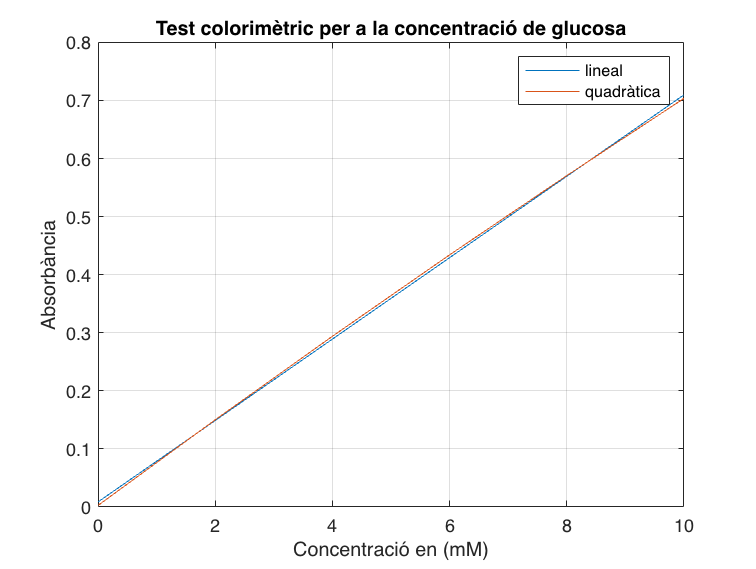

% %Càlculs per fer
% plottools
hold on
plot(x,c + b*x + a*x.^2, 'DisplayName',sprintf('quadràtica'))
hold off

### 3.- Mètodes iteratius

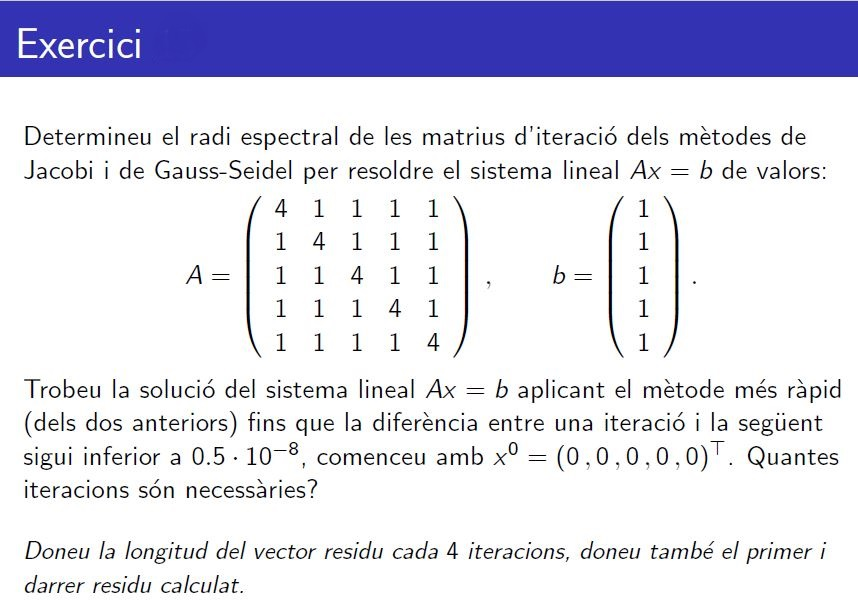

% Càlculs per fer
A = [4 1 1 1 1; 1 4 1 1 1; 1 1 4 1 1; 1 1 1 4 1; 1 1 1 1 4];
b = [1; 1; 1; 1; 1];

D = diag(diag(A));
d = diag(1 ./ diag(A));

L = tril(A,-1);
U = triu(A,1);

`EXERCICI: 1) Matriu d'iteració i radi del mètode de Jacobi `

% Càlculs per fer
Bj = -d*(A-D); %matriu iteració
cj = d*b; %vector

rhoJ = max(abs(eig(Bj))); %radi espectral del mètode de Jacobi

if (rhoJ + eps >= 1) resp = "mètode de Jacobi divergent";
else resp = "mètode de Jacobi convergent";
end

jacobi = {rhoJ, resp}';

`EXERCICI: 2) Matriu d'iteració i radi del mètode de Gauss-Seidel`

% Càlculs per fer
dG = inv(L+D);
Bgs = -dG*U; %matriu iteració
cgs = dG*b; %vector

rhoGS = max(abs(eig(Bgs))); %radi espectral del mètode de Gauss-Seidel

if (rhoGS + eps >= 1) resp = "mètode de GAUSS-SEIDEL divergent";
else resp = "mètode de GAUSS-SEIDEL convergent";
end

gauss = {rhoGS, resp}';

table(jacobi, gauss, 'VariableNames',{'Jacobi','Gauss-Seidel'})

ans = 2×2 table
                 Jacobi                              Gauss-Seidel              
    ________________________________    _______________________________________

    {[                      1.0000]}    {[                             0.2509]}
    {["mètode de Jacobi divergent"]}    {["mètode de GAUSS-SEIDEL convergent"]}


`EXERCICI: 3) Iteracions i vector residu`

%mètode de Jacobi
if rhoJ >= 1
    error('mètode de Jacobi divergent')
else %(rhoJ < 1)
    n = 10000; i = 0; 
    x = zeros(size(b));
    tol = 0.5e-8;
    criteriParada(1) = 1;
    while(i < n && criteriParada(max(i,1)) > tol)
        i = i+1; y = Bj*x+cj;
        residu(i) = norm(b-A*y,'inf');
        e(i) = norm(y-x,'inf');
        delta(i) = norm(y-x,'inf');
        criteriParada(i) = delta(i)/norm(y,'inf');
        x = y;
    end
   table(residu',e',delta',criteriParada','VariableNames',{'residu','e^k','delta^k','stop'})
   table(i, residu(1), residu(end), 'VariableNames',{'# iteracions', 'Primer Residu', 'Darrer Residu'})
   x(1);
end

ans = 10000×4 table
    residu    e^k     delta^k    stop
    ______    ____    _______    ____

      1       0.25     0.25        1 
      1       0.25     0.25      Inf 
      1       0.25     0.25        1 
      1       0.25     0.25      Inf 
      1       0.25     0.25        1 
      1       0.25     0.25      Inf 
      1       0.25     0.25        1 
      1       0.25     0.25      Inf 
      1       0.25     0.25        1 
      1       0.25     0.25      Inf 
      1       0.25     0.25        1 
      1       0.25     0.25      Inf 
      1       0.25     0.25        1 
      1       0.25     0.25      Inf 
      1       0.25     0.25        1 
      1       0.25     0.25      Inf 


ans = 1×3 table
    # iteracions    Primer Residu    Darrer Residu
    ____________    _____________    _____________

       10000              1                1      


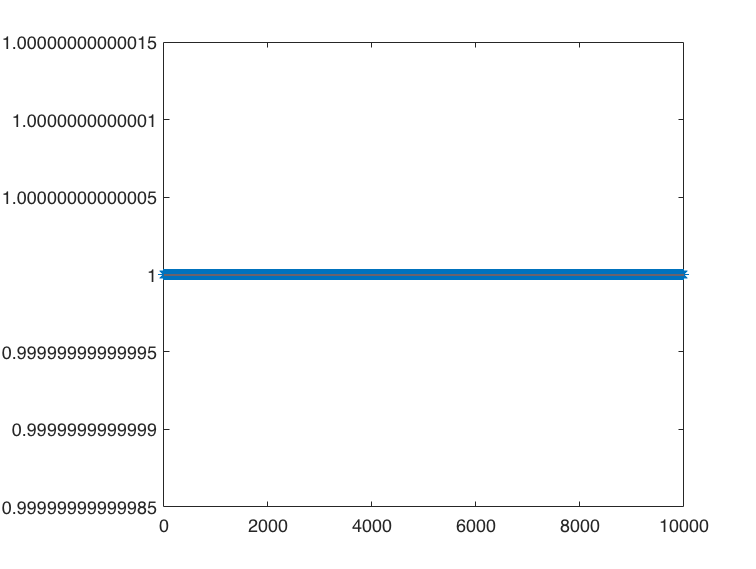

%És interessant estudiar com evoluciona: delta^k/delta^k-1
ratio = delta(2:end) ./ delta(1:end-1);
plot(ratio,'-*')
hold on
plot(rhoJ * ones(size(ratio)))
hold off

%mètode de Gauss
clear residu criteriParada e delta
if rhoGS >=1
    error('mètode de gauss-seidel divergent')
else
    n = 10000; i = 0; 
    x = zeros(size(b));
    tol = 0.5e-8;
    criteriParada(1) = 1;
    while(i<n && criteriParada(max(i,1)) > tol)
        i = i+1; y = Bgs*x+cgs;
        residu(i) = norm(b-A*y,'inf');
        e(i) = norm(y-x,'inf');
        delta(i) = norm(y-x,'inf');
        criteriParada(i) = delta(i)/norm(y,'inf');
        x = y;
    end
   table(residu',e',delta',criteriParada','VariableNames',{'residu','e^k','delta^k','stop'})
   table(i, residu(1), residu(end), 'VariableNames',{'# iteracions', 'Primer Residu', 'Darrer Residu'})
   x(1);
end 

ans = 16×4 table
      residu         e^k         delta^k         stop   
    __________    __________    __________    __________

        0.5127          0.25          0.25             1
      0.063575       0.12817       0.12817       0.92318
      0.020542      0.014664      0.014664       0.11441
     0.0053388     0.0051356     0.0051356      0.040906
     0.0010423     0.0012883     0.0012883      0.010297
    0.00034021    0.00024391    0.00024391     0.0019496
    8.6249e-05    8.5052e-05    8.5052e-05    0.00068031
     1.623e-05    2.0859e-05    2.0859e-05    0.00016687
    5.3406e-06    4.0423e-06    4.0423e-06    3.2338e-05
    1.3538e-06    1.3351e-06    1.3351e-06    1.0681e-05
    2.6178e-07    3.3845e-07    3.3845e-07    2.7076e-06
    8.2562e-08    6.4804e-08    6.4804e-08    5.1843e-07
    2.1739e-08    2.0641e-08    2.0641e-08    1.

ans = 1×3 table
    # iteracions    Primer Residu    Darrer Residu
    ____________    _____________    _____________

         16            0.5127         3.4893e-10  


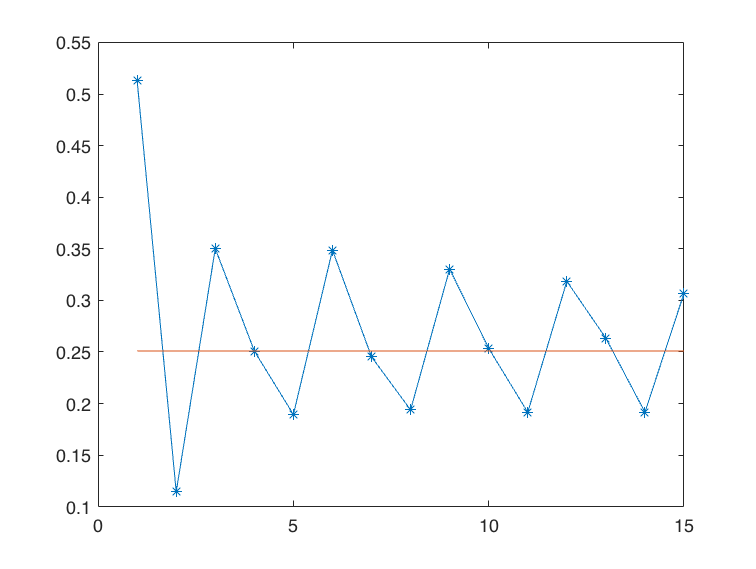

%És interessant estudiar com evoluciona: delta^k/delta^k-1
ratio = delta(2:end) ./ delta(1:end-1);
plot(ratio,'-*')
hold on
plot(rhoGS * ones(size(ratio)))
hold off

`Document preparat per M. Àngela Grau Gotés, 10 de març de 2022`